cla reset;

- **Рассичитать в программе Mathcad линейчаты спектр периодической последовательности прямоугольных импульсов при alpha = 0.05**

N = 20;
AM = 1;
alpha = 0.05;


$$\begin{array}{l}
A_k =\frac{2}{\pi }\int_0^{\pi } Z\left(x\right)\cdot \cos \left(k\cdot x\right)dx\\
A_0 =\frac{1}{\pi }\int_0^{\pi } Z\left(x\right)dx\\
{\mathrm{AD}}_k =\kappa \cdot \log \left(\frac{|A_k |}{A_1 }\right)
\end{array}$$


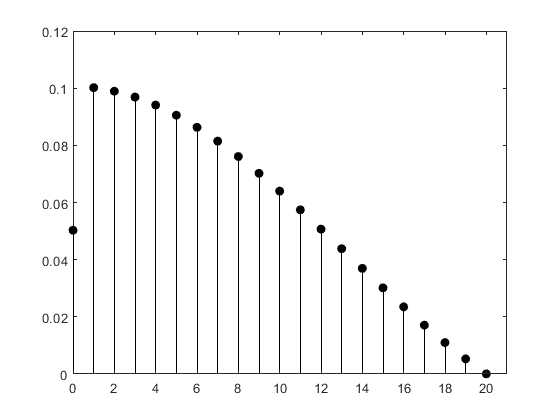

ans = table
         A     
    ___________

    1×21 double


ans = table
        AD     
    ___________

    1×21 double


spectrplot(N, AM, alpha, "plot1_1.jpg")

    2. **Рассчитаем в программе Mathcad линейчатый спектр периодической последовательности прямоугольных импульсов при 𝛼 = 0,2**

ans = table
         A     
    ___________

    1×21 double


ans = table
        AD     
    ___________

    1×21 double


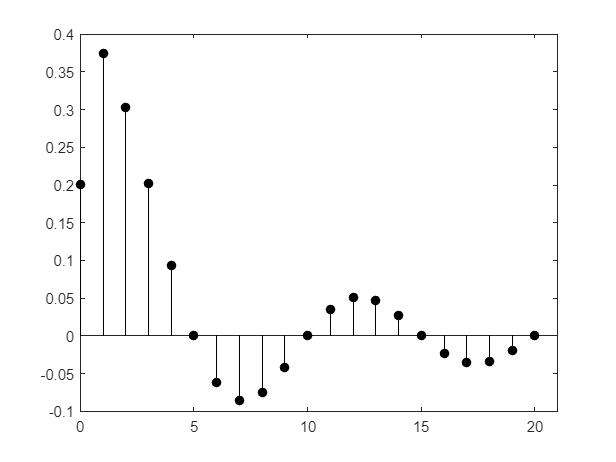

alpha = 0.2;
spectrplot(N, AM, alpha, "plot1_2.jpg")

      3. **Рассчитаем в программе Mathcad линейчатый спектр периодической последовательности прямоугольных импульсов при 𝛼 = 0,5**

ans = table
         A     
    ___________

    1×21 double


ans = table
        AD     
    ___________

    1×21 double


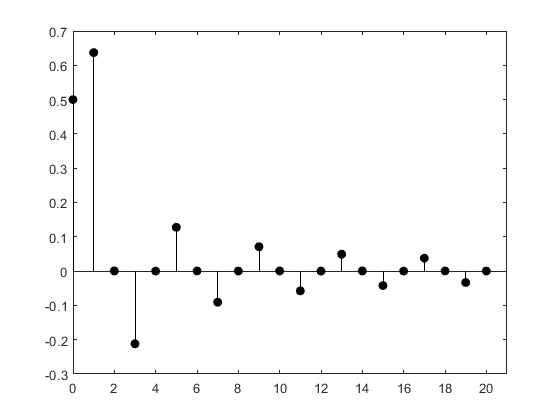

alpha = 0.5;
spectrplot(N, AM, alpha, "plot1_3.jpg")

     4. **Рассчитаем спектр при 𝛼 = 0,5 по формуле указанной ниже и сравним полученный результат со значениями полученными по программе в пункте 3. **

k = (1:(N+1)) - 1; k(1) = 1.2067;


$$A_k =2\cdot \frac{\mathrm{AM}}{\pi \cdot k}\cdot \sin \left(\pi \cdot k\cdot \alpha \right)$$


t = 2 * (AM./(pi.*k).*sin(pi.*k.*alpha));
table(t)

ans = table
         t     
    ___________

    1×21 double


function spectrplot(N, AM, alpha, filename)
k = 0:N;
A = Ak(N, alpha, AM);
table(A)
AD = 8.684 * log(abs(A)/A(2));
table(AD)
stem(k, A, 'LineStyle','-', 'Color','black', 'MarkerFaceColor','black');
xlim([0 21]);
saveas(gcf, filename);
end

function A = Ak(N, alpha, AM)
    p = zeros(1, (N + 1));
    for k = 0:N
        if k == 0
            ak = A0(alpha, AM);
            p(k + 1) = ak;
            continue;
        end
        ak = 0;
        for i = 0:0.001:pi
            y = Z(i, alpha, AM);
            ak = ak + y * cos(k * i);
        end
        ak = (2/pi)*ak/1000;
        p(k +1) = ak;
    end
    A = p;
end

function z = A0(alpha, AM)
    z = 0;
    for i = 0:0.001:pi
        y = Z(i, alpha, AM);
        z = z + y;
    end
    z = (1/pi)*z/1000;
    return;
end

function y = Z(x, alpha, AM)
    if abs(x) <= (alpha * pi)
        y = AM;
        return;
    end
    if isequal(((alpha * pi) <= abs(x)), (abs(x) <= pi))
        y = 0;
        return;
    end
end